# About this file

                    This file serves as an application note for functions used from mapping toolbox. These functions are extensively used in the LOS Calculator App, so this file provides brief introduction of all used functions in one place. This is helpful if someone else is trying to understand the code base. Contents are divided into two sections: axesm mapps and geoaxes maps. These two map catergories have a lot of differences, so, a summary about them will be helpful!

# Using axesm based maps

The **axesm** function creates an axesm-based map (previously referred to as map axes) into which both vector and raster geographic data can be projected using functions such as plotm and geoshow.

ax=axesm('MapProjection','eqdconic','MapLatLimit',[23 36],'MapLonLimit',[60 75],'Origin',[32.5059 71.5637]);

In above call, 'MapProjection' property must be set. All others can be left to defaults. See 'Summary and guide to projections' in help for more details.

To avoid warning, omit Lat/Lon limits if origin is NonZero.

Use the `axesm` function only to *create* an `axesm`-based map. Use the `setm` function to *modify* an existing `axesm`-based map. e.g to see and modify frame line borders:

getm(gca,'FLineWidth')

ans = 2

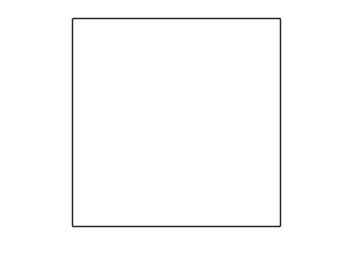

setm(gca,'FLineWidth',4)

To see all the properties at once:

getm(gca)

ans = struct with fields:
     mapprojection: 'eqdconic'
              zone: []
        angleunits: 'degrees'
            aspect: 'normal'
     falsenorthing: 0
      falseeasting: 0
       fixedorient: []
             geoid: [1 0]
       maplatlimit: [-90 90]
       maplonlimit: [-180 180]
      mapparallels: [15 75]
        nparallels: 2
            origin: [32.5059 71.5637 0]
       scalefactor: 1
           trimlat: [-90 90]
           trimlon: [-135 135]
             frame: 'off'
             ffill: 100
        fedgecolor: [0.1500 0.1500 0.1500]
        ffacecolor: 'none'
         flatlimit: [-90 90]
        flinewidth: 4
         flonlimit: [-135 135]
              grid: 'off'
         galtitude: Inf
            gcolor: [0.1500 0.1500 0.1500]
        glinestyle: ':'
        glinewidth: 0.5000
    mlineexception: []
         mlinefill: 100
        mlinelimit: []
     mlinelocation: 30
      mlinevisible: 'on'
    plineexception: []
         plinefill: 100
        plinelimit: []
  

**To get coordinates **from axesm map, pt=**gcpmap** returns the current point (last point on map under mouse cursor) of the current axesm-based map in the form [latitude longitude z-altitude].

pt = gcpmap(map_handle) returns point from the map specified by its handle.

pt = gcpmap(ax)

pt =    48.3821   88.8382    1.0000
   48.3821   88.8382         0


 **To get input** from axes-m based map, use **inputm** function:

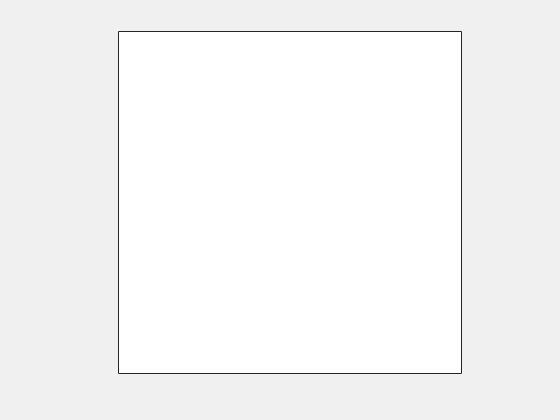

lats = 75.0518

lons = 150.6033

interrupts = 1

[lats,lons,interrupts]=inputm(4) % get coords of 4 points and key/mouse used for entering pts

*Note that inputm function can only be used with axes-m based maps.*

*Similarly, to plot data on axes-m based maps, geoshow is used. To plot data on geoaxes based map, geoplot and geoplot3 are used.*

**To Plot Line** in axesm, use *linem* instead of *line*

axes(ax);
% linem(latitude, longitude,Name_value_arguments ...)
linem([32.5059 32.5062],[71.5637 71.55737],'Color','red');

**To plot text **in axesm based maps, use **textm** function instead of text

axes(ax) % make ax the current axes
% textm(latitude, longitude, text,Name_value_arguments ...)
t=textm(32.5059,71.5637,0,'this is text','Color','r','FontSize',20)

**To Plot polygon** regions so that they are identified in legend, use the '**patchm**' function instead of standard *patch* function:

*Always switch axes to axesm map, otherwise, patchm will try to plot in current axes and may fail if figure does not have axesm map*

axes(ax) % switch axes to valid axesm map
color_vector=[0.5 0.2 0.6];
p2=patchm(lats,lons,color_vector);

**NOTE:**The patch and patchm functions do not take into account the order of polygon vertices. However, most of mapping toolbox functions consider vertices to be in clockwise order. So, while plotting on axesm based maps, use the** 'poly2cw'** function to arrange vertices in CW order. Note that x should be longitude vector and y should be latitude vector

[lon,lat] = poly2cw(lons, lats); % caution! x=longitude, y=latitude
% now plot using patchm
axes(ax) 
p2=patchm(lat,lon,color_vector);

To check if current map is axesm based or not, use **ismap** function:

[check,reason]=ismap(ax)
% check=true means ax is axesm based
% if check=false, reason will mention why its not axesm based map

# Geo-axes based maps

`geoaxes` creates a geographic axes in the current figure using default property values, and makes it the current axes.

A geographic axes displays data in geographic coordinates (latitude/longitude) on a map. The map is *live*, that is, you can pan to view other geographic locations and zoom in and out on the map to view regions in more detail.

clear all, clc, close all;
fig=figure; % CAUTION: user figure instead of 'uifigure', ow, ginput will fail
 % create geoaxes
gx=geoaxes(fig)
gx.Basemap='street'
geoplot(gx,32.5059,71.5637,'Marker','+')

**To get coordinates**, use ginput function:

[lat long]=ginput(4) % get coords of 4 points

**Set axes properties after plotting** since some graphics functions reset axes properties. Use gca to get current axis, as some plotting functions may create new axes.

h=geoplot(gx,32.5059,71.5637,'Marker','+'); % plot a point
% gx=gca; % get the axes, however not necessary if we supplied gx to
% geoplot in above call
gx.Basemap='satellite'; % set properties of geoaxes after ploting
enableDefaultInteractivity(gx);
gx.LatitudeAxis.Visible='off';
gx.LongitudeAxis.Visible='off';

**To delete the specific plot/line/point etc**, use its handle:

delete(h) % delete doesn't affect geoaxis properties

**To reset/clear all the plots** and set properties to default, use 'cla'

cla reset

**To add callback **for mouse scroll and button press, use set property of figure:

breakpoint=0;
set(fig,'WindowScrollWheelFcn',@(src,event)mouseMove(src,event,gx))
% src and event are passed autmatically by matlab to every callback
% another better way to set callbacks with our specified parameters is:
set(fig,'WindowButtonDownFcn',{@mouse_button_press_callback,gx})
% in above statement, src and event are passed automatically. So,
% the calback fcn should either accept three arguments or reject first
% two arguments(use ~ notation)
% see end of this file for callback definitions

In callbacks, if you need to share data among callbacks, you can use the the **UserData **property(see help for 'share data among callbacks'):

% inside callback,store data in UserData property of source or fig
fig.UserData=struct('lat',lat,'long',long);

To diffrentiate between different mouse click types, use the** 'SelectionType'** property of the figure of interest:

% this code is usually placed in 'WindowButtonDownFcn' callback routine
fig_handle=fig;
sel=fig_handle.SelectionType;
switch(sel)
    case 'alt' % left or right button pressed
        disp('right button');
    case 'normal' % only left button pressed
        disp('left button');
    case 'open' % double click on either button
        disp('double click');
    otherwise %scroll wheel click
        disp('unknwon button press');
end
% see 'Figure Properties' in help for more detail

**To plot shaded regions **in geoaxes based map, use geopolyshape,geolineshape,mapshape etc.

cla reset
x=[32.5059 32.5059 32.5069 32.5069 32.5059];
y=[71.5637 71.5647 71.5647 71.5637 71.5637];
shape=geopolyshape(x,y);
geoplot(gx,shape,'EdgeColor','r','FaceColor','g','FaceAlpha',0.5,'LineStyle','--');

To change the base map programatically, query the zoom level and load appropriate map(use WindowScrollWheelFcn callback):

current_zoom=gx.ZoomLevel;
if current_zoom==7
    gx.Basemap='pak_terrain_7' % zoom level 7 custom map
end

# Adding Custom Basemaps

Select the parrent folder from where this script can locate all mbtiles by zoom level.

level=12;
% dir=uigetdir % get directory for folder where all mbtiles can be accesed with their folder names
dir = 'C:\downloads';
folder='\\terrain_map_L%d\\terrain_map_L%d_combined\\terrain_map_L%d.mbtiles'
file_name=sprintf(folder,level,level,level)
file_path=[dir,file_name]
exist(file_path)
map_name=['terrain_map_L' char(string(level))]

addCustomBasemap(map_name,file_path,'Attribution','Developed by Radar Div NASTAP','IsDeployable',true)

**Note** that when custom maps are used, you need to load also custom terrain data in the site viewer, otherwise, calculations using terrain will fail if no internet connection exists. These calculations, in our app, are distance b/w tx-rx, los, elevation etc. 

Also note that before perfroming any calculation on tx/rx objects (e.g distance), site viewer object should be created with custom basemap and custom terrain to work offline.

# Using This code on other PC

In order to successfuly run this app on another PC, you need to Add the custom terrain 'Pak_Master_2 and add the custom basemaps from mbtiles. To add custom basemaps, you can use the script file 'test_script.m'. Place all the mbtile files at the same folder and then run this script. When prompted, select the folder where you placed mbtile files. After adding custom maps and custom terrain, you can use this app while offline.

#### Example Callbacks:

function mouseMove (~,event,handle)
newpt=handle.CurrentPoint; % get current point under cursor
handle.MapCenter=[newpt(1,1),newpt(1,2)] % and set it as new map center
if(event.VerticalScrollCount>0)
    handle.ZoomLevel=handle.ZoomLevel-0.1250;
elseif(event.VerticalScrollCount<0)
    handle.ZoomLevel=handle.ZoomLevel+0.1250;
end
pause(0.2)
end

function mouse_button_press_callback(fig_handle,event,map_handle)
% fig_handle.WindowScrollWheelFcn=[];
% fig_handle.WindowButtonDownFcn=[];
disp('button down callback')
% enableDefaultInteractivity(map_handle);
% map_handle.Interactions=[panInteraction,zoomInteraction];
sel=fig_handle.SelectionType;
switch(sel)
    case 'alt'
        pts=map_handle.CurrentPoint;
        map_handle.MapCenter=[pts(1,1) pts(1,2)];
        disp('right button');
    case 'normal'
        disp('left button');
    otherwise 
        disp('unknwon button press');
end

end